# Creat Grid Map

`@author: Winter`

`@update: 2023.1.29`

## function import

addpath("env\");

## map A

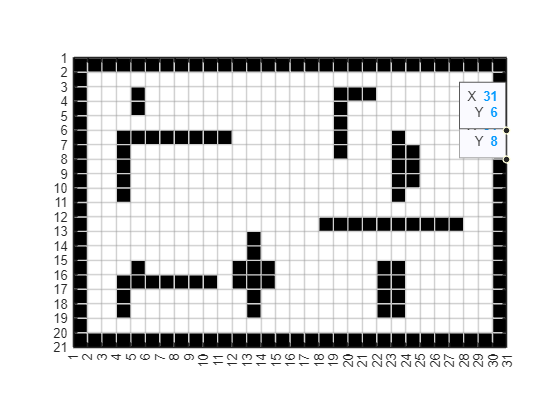

clear all;
clc;

% map setting
map_size = [20, 30];
G = 1;

% obstacle
obs0 = [1:map_size(1), ... 
        map_size(1):map_size(1):map_size(1) * map_size(2), ...
        1:map_size(1):(map_size(1) - 1) * map_size(2), ...
        map_size(1) * (map_size(2) - 1):map_size(1) * map_size(2)];
obs1 = [66, 76, 86, 96, 106, 116, 126, 136, 146, 156, 166, 176, 186, 196, 206];
obs2 = [66, 67, 68, 69, 70];
obs3 = [83, 84, 95, 76, 96, 77, 78];
obs4 = [253, 254, 235, 255, 275, 236, 256, 276, 257, 258];
obs5 = [352, 372, 392, 412, 432, 452, 472, 492, 512, 532];
obs6 = [435, 436, 437, 438, 455, 456, 457, 458];
obs7 = [363, 364, 365, 366, 367, 383, 403];
obs8 = [446, 447, 448, 449, 450, 467, 468, 469];
obstacle = [obs0, obs1, obs2, obs3, obs4, obs5, obs6, obs7, obs8];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
save gridmap_20x20_scene1 grid_map
plot_grid(grid_map);

xlim([1.0 31.0])
ylim([1.0 21.0])
 
ax = gca;
chart = ax.Children(43);
datatip(chart,31,8);
chart = ax.Children(45);
datatip(chart,31,6);

## map B

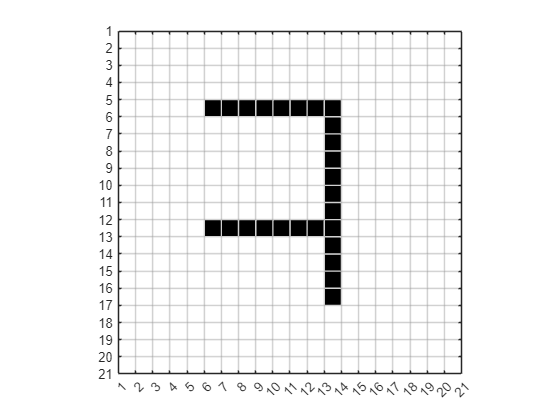

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1;

% obstacle
obstacle = [105, 125, 145, 165, 185, 205, 225, 245, 246, 247, 248, 249, 250, 251, ...
        252, 253, 254, 255, 256, 232, 212, 192, 172, 152, 132, 112];
    
% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene2 grid_map
plot_grid(grid_map);

## map C

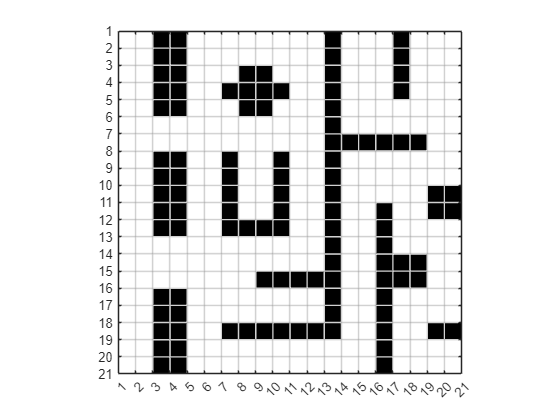

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1;    

% obstacle
obs1 = [56, 57, 58, 59, 60, 76, 77, 78, 79, 80];
obs2 = [241, 242, 243, 244, 245, 246, 247, 248, 249, 250, 251, 252, 253, 254, 255, 256, 257, 258];
obs3 = [128, 129, 130, 131, 132, 152, 172, 192, 191, 190, 189, 188];
obs4 = [311, 312, 313, 314, 315, 316, 317, 318, 319, 320];
obs5 = [138, 158, 178, 198, 218, 238, 175, 195, 215, 235, 255];
obs6 = [124, 144, 164, 184, 143, 163, 145, 165];
obs7 = [267, 287, 307, 327, 347, 321, 322, 323, 324];
obs8 = [370, 390, 371, 391, 334, 354, 335, 354, 355, 378, 398];
obstacle = [obs1, obs1- 8, obs1 - 15, obs2, obs3, obs4, obs5, obs6, obs7, obs8];
    
% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene3 grid_map
plot_grid(grid_map);

## map D

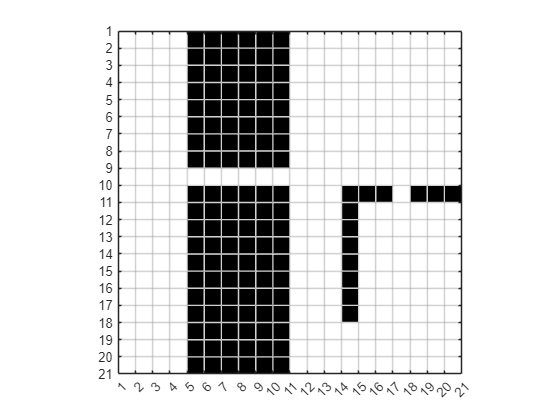

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs1 = 81:88;
obs2 = 90:100;
obs3 = 270:277;
obs4 = [290, 310, 350, 370, 390];

obstacle = [obs1, obs2, obs1 + 20, obs2 + 20, obs1 + 40, obs2 + 40, obs1 + 60, obs2 + 60, obs1 + 80, obs2 + 80, ...
    obs1 + 100, obs2 + 100, obs3, obs4];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);

## 测试

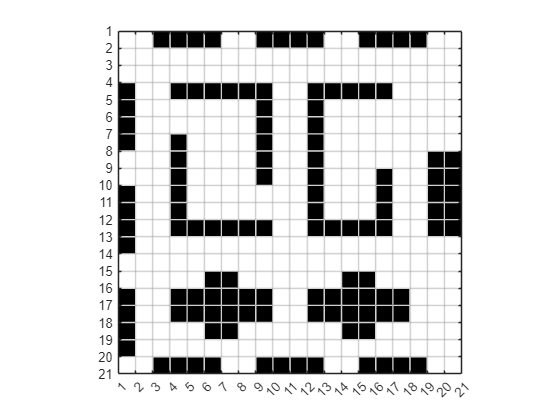

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs1 = 4:7;
obs2 = [41, 61, 81, 101];
obs3 = 368:372;
obs4 = [64,84, 104, 124, 144, 164, 165, 166, 167, 168, 169];
obs5 = [67, 68, 69, 70, 71, 72, 92, 112, 132, 152, 172];
obs6 = [76, 77, 96, 97, 115, 116, 117, 118, 135, 136, 137, 138, 156, 157, 176, 177];
obs7 = [224, 225, 226, 227, 228, 229, 230, 231, 232, 244, 264, 284, 304, 252, 272, 292, 312, 311, 310, 309];

obstacle = [obs1, obs1 + 6, obs1 + 12, obs2, obs2 + 120, obs2 + 240, obs2 + 19,...
            obs2 + 139, obs2 + 259, obs3, obs3 + 20, obs4, obs5, obs6, obs6 + 160, obs7];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);

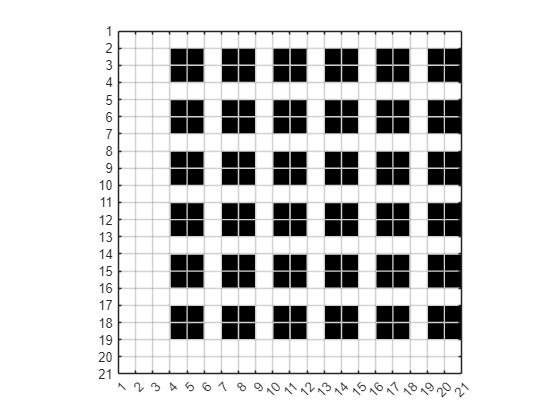

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs = [62, 63, 82, 83];
obstacle = [];
for i=0:5
    for j=0:5
        obs_ = obs + 60 * i + 3 * j;
        obstacle = [obstacle, obs_];
    end
end
% obstacle = [obs, obs + 60];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);